clear
clc
close all

% t = 0:1:3600;
amp = 1.5;
period = 10;
% y = amp*sin(t/p);
% 
% d = diff(y);
% val = subs(d,x,pi/2);
% plot(t, y);

syms x t;
hold on
f = amp*sin(2*pi*x / period);
disp(f);

$$\frac{3\,\sin\left(\frac{\pi \,x}{5}\right)}{2}$$


d = diff(f,x);
disp(d);

$$\frac{3\,\pi \,\cos\left(\frac{\pi \,x}{5}\right)}{10}$$


g = atan(d);
disp(g);

$$\mathrm{atan}\left(\frac{3\,\pi \,\cos\left(\frac{\pi \,x}{5}\right)}{10}\right)$$


m = atan(d);
disp(m);

$$\mathrm{atan}\left(\frac{3\,\pi \,\cos\left(\frac{\pi \,x}{5}\right)}{10}\right)$$



%t = 0:.3:2*pi;
ang_eq = @(t) (subs(m,t));

t = [0];
h = 1.0;
tol = 0.2;
angle = subs(m,t);

while t(end) < period
    t_1 = t(end) + h;
    
    angle_1 = subs(m,t_1);
    error = abs(angle_1-angle);
    
    if error < tol
        angle = angle_1;
        t = [t, t_1];
        
        h = 2.0 * h;
        
        if (t(end) + h) > period
            h = period - t(end);
        end
        
    else
        h = 0.9 * h;
    end
end

disp(length(t))

    19



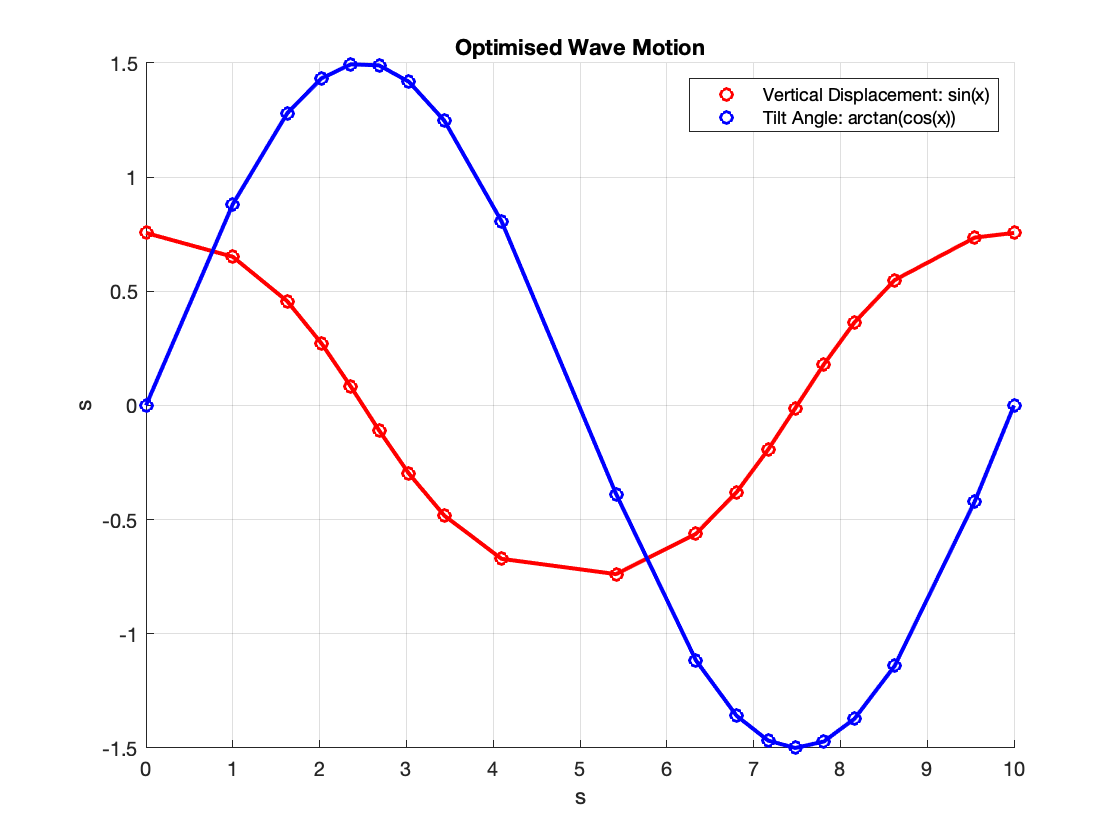



ang = double(subs(g, t));
disp = double(subs(f, t));




grid on
% lims=[0 period];
% xlim(lims)
o_t = 0:10;
fplot(o_t,subs(m,o_t), "o", "Color", "r", 'LineWidth',1.5);
fplot(o_t,subs(m,o_t), "Color", "r", 'LineWidth',2);
fplot(o_t,subs(f,o_t), "o",  "Color", "b", 'LineWidth',1.5);
fplot(o_t,subs(f,o_t),  "Color", "b", 'LineWidth',2);
legend("Vertical Displacement: sin(x)","", "Tilt Angle: arctan(cos(x))");
title("Wave Motion")
figure(2);
hold on
grid on
plot(t, subs(m,t), "o", "Color", "r", 'LineWidth',1.5);
plot(t, subs(m,t),  "Color", "r", 'LineWidth',2);
plot(t, subs(f,t), "o",  "Color", "b", 'LineWidth',1.5);
plot(t, subs(f,t),  "Color", "b", 'LineWidth',2);
xlabel("s")
ylabel("s")
legend("Vertical Displacement: sin(x)","", "Tilt Angle: arctan(cos(x))");
title("Optimised Wave Motion")